# Plots node pressure for a specific time.

## This function contains: 

- Load a network. 

- Hydraulic analysis using EN functions. 

- Plot pressure after d.plot. 

- Plot pressure only nodes. 

- Unload library.

## Clear - Start Toolkit

clear; close('all'); clc;
start_toolkit;

EPANET-MATLAB Toolkit Paths Loaded.
EPANET version {20305} loaded (EMT version {v2.3.5.2 - Last Update: 03/03/2026}).
<a href = "https://doi.org/10.5281/zenodo.831493">Publication DOI: 10.5281/zenodo.831493</a>
Loading File "Net1.inp"...
Input File "Net1.inp" loaded successfully.


ans = int32
   11


EPANET Class is unloaded


## Load a network.

inpname = 'Net2.inp';
d = epanet(inpname);

EPANET version {20305} loaded (EMT version {v2.3.5.2 - Last Update: 03/03/2026}).
<a href = "https://doi.org/10.5281/zenodo.831493">Publication DOI: 10.5281/zenodo.831493</a>
Loading File "Net2.inp"...
Input File "Net2.inp" loaded successfully.


## Hydraulic analysis using EN functions.

values = d.getComputedHydraulicTimeSeries;
press = values.Pressure;
flow = values.Flow;
coords = d.getNodeCoordinates;

## 1. Plot pressure at hour 1

## Show type of node

d.plot('legendposition', 'best')

ans =   Axes with properties:

             XLim: [6.5 60.5]
             YLim: [-4.3 95.3]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.13 0.11 0.775 0.815]
            Units: 'normalized'

  Show all properties


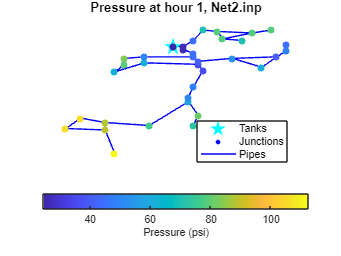

hold on
for i=1:length(press(1,:))
    scatter(coords{1}(i),coords{2}(i),35, press(1,i), 'filled')
end
title(['Pressure at hour 1, ', inpname])
c = colorbar('southoutside');
c.Label.String = ['Pressure (', d.NodePressureUnits, ')'];

## 2.Plot pressure at hour 1

## Hide type of node

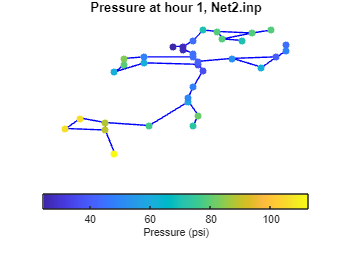

d.plot('point', 'no', 'legend', 'hide');
hold on
for i=1:length(press(1,:))
    scatter(coords{1}(i),coords{2}(i),35, press(1,i), 'filled')
end
title(['Pressure at hour 1, ', inpname])
c = colorbar('southoutside');
c.Label.String = ['Pressure (', d.NodePressureUnits, ')'];

## Unload library.

d.unload

EPANET Class is unloaded
